close all;
clear all;
clc;

N=256; % signal length
M=120; % select the number of DCT coefficients

%% Load the test signal
% Is load to array in mem on tellos mote B
load mit200
x= ecgsig(1:N, 1);

%% DCT transform of signal from telos B mote 
y = [-57.3500 30.5297 -22.2311 9.9035 -2.2880 10.2281 11.2077 -6.938 16.4929 -10.6609 19.80 -7.8218 14.7577 -2.8769 4.6811 6.6271 -3.3766 10.8228 -5.3004 7.5430 0.1389 0.3303 6.603 -6.764 8.9963 -6.2909 4.7111 0.9716 0.5961 3.1026 -3.6961 3.3411 -3.9260 0.3250 -1.6927 -2.4813 0.3568 -3.8334 0.6039 -2.9579 0.7917 -1.6674 -1.8172 -1.5610 -1.7754 -1.4271 0.5582 -1.695 0.300 0.8309 0.3641 0.8135 0.2775 0.4120 0.1497 1.163 0.722 1.1543 0.2689 1.36 0.4185 0.1301 1.6235 0.69 1.7447 0.7001 1.905 0.8698 0.2905 0.4809 0.2217 0.3332 0.5261 0.809 0.5748 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 0.0 ];
% Scale the signal
y(1)=1/sqrt(N)*y(1);
y(2:end)=sqrt(2/N)*y(2:end);

%% reconstructed signal
x_rec=idct(y);

%% Mean squre error
mse(x,x_rec)

ans = 0.1554

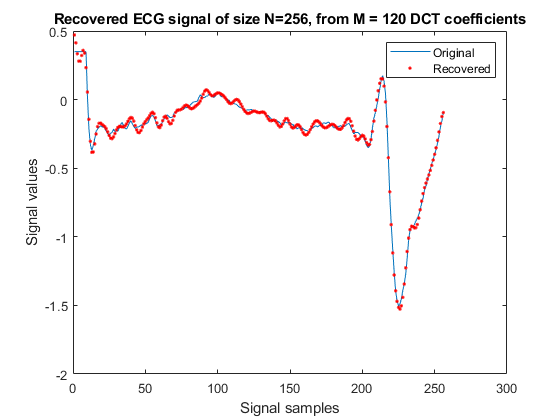

% Plot original
plot(x);

hold on;
% Plot restored
plot((x_rec) , 'r.' ) ;
title('Recovered ECG signal of size N=256, from M = 120 DCT coefficients');
xlabel('Signal samples'); 
ylabel('Signal values'); 
legend ('Original', 'Recovered');